### Converting Arbitrary Linear Function to Matrix  (func2mat)

The function func2mat() is a fully general utility in this submission. It will obtain the matrix representation of any N-dimensional to M-dimensional linear mapping, with no further assumptions on the structure of the function other than linearity. Below is a simple example where `func2mat` is used to obtain the matrix equivalent of the linear operation `fft(P*X,50,2)*Q` where X is a 10x12 input matrix and P and Q are known matrices.

P=rand(10); Q=rand(50,3); Xtypical=zeros(10,12);

fcn=@(z) fft(P*z,50,2)*Q; %hypothetical linear function

A=func2mat(fcn,Xtypical); %The equivalent matrix

%%%Test the equivalence%%%

X=rand(size(Xtypical));

Y1=fcn(X); %use the function

Y2=reshape( A*X(:) ,size(Y1)); %use matrix multiplication 

difference = norm(Y1-Y2,'fro') %#ok<*NASGU> 

difference = 1.8999e-13

We see that `Y1` and `Y2` agree within very small error.

The approach to computing A is largely brute force. If A is MxN, then the code works essentially by applying fun to each column of eye(N) in a loop. Because this can be a slow process, options are available to leverage the Parallel Computing Toolbox if you have it,

                           ` A=func2mat(fun,Xtypical,'UseParallel',1)`

This assumes a parpool is already open.  By default, A is computed as a sparse matrix, but if sufficiently small/dense, it is sometimes  more efficient memory-wise and speed-wise to compute A in full form,

                         `  A=func2mat(...,'doSparse',0)`

### Image Transformations with Localized Responses (localfunc2mat)

The distribution also contains `localfunc2mat()`, a more high-speed alternative to `func2mat()`. However, `localfunc2mat()` is applicable to a narrower class of linear functions.  In particular, it applies to linear image transformations where if two input pixels are a sufficient separation distance `D` apart, they will not affect the same output pixels. This property is often satisfied for common image rotations and warpings. 

The usage of `localfunc2mat()` is demonstrated below, where we obtain the matrix equivalent to `imrotate(x,-30)`. When linear interpolation is used, `imrotate()` satisfies the above property for separation distances `D=2`.

xsiz=[256,256]; %input image size
D=2; %separation distance ("influence width').

fcn=@(x) imrotate(x,-30,'crop'); %desired rotation operation


tic;
[A,ysiz]=localfunc2mat(fcn,xsiz,D); %convert to matrix form
toc

Elapsed time is 1.100902 seconds.


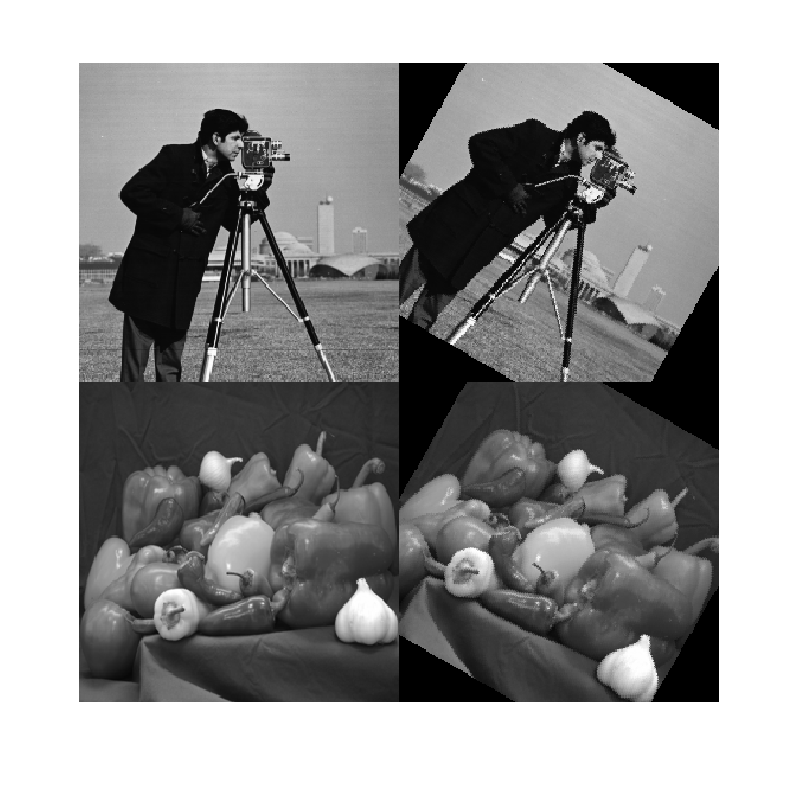



X1=imresize( double(im2gray(imread('cameraman.tif')))  ,xsiz);
X2=imresize( double(im2gray(imread('peppers.png')))  ,xsiz);


Y1=reshape( A*X1(:) , ysiz); %rotate images with matrix multiplication
Y2=reshape( A*X2(:) , ysiz);


montage({X1,Y1,X2,Y2},'DisplayRange',[0,256],'Size',[2,2])

To illustrate the speed benefits of `localfunc2mat,` it is worth repeating the matrix calculation using the more general `func2mat` utility,

tic
  A2=func2mat(fcn,X1);
toc

Elapsed time is 15.589116 seconds.



difference=norm(A-A2,'fro')

difference = 0

We see that the speed-up offered by  is considerable. The performance gap will widen for larger image dimensions and for smaller `D`.